## Concrete column with variable section area

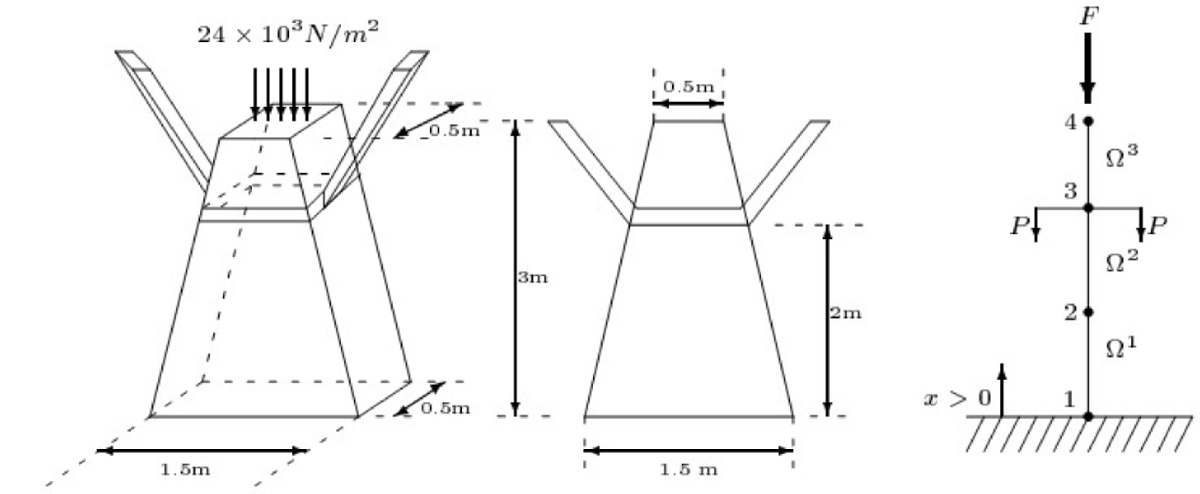

$\copyright$Numerical Factory

**Figure 1.** Dimensions of the piece, transverse section, loads, frontal plant, and meshing in 3 linear elements of lenght $h = 1\text{m}$ (image taken from professor Antonio Susin's Numerical Factory).

Consider,

    
$$\begin{array}{ll}
P = 2\times 10^{3} \text{N}, & h = 1 \text{m},\\
E = 28\times 10^{9} \text{N/m}^{2}, & w = 25\times 10^{3} \text{N/m}^{3} \text{ (concrete specific weight)}. 
\end{array}$$


clearvars
close all

### Real constants

    
$$\begin{array}{rcll}
  E &=& 28\times 10^{9} \text{N/m}^{2}, &\text{(Young modulus)},\\
  w &=& 25\times 10^{3} \text{N/m}^{3}, & \text{(concrete specific weight)}.\\
\end{array}$$


%Real constants

E = 28.0e9;           %N/m^2
w = 25.0e3;           %N/m^3

P = 2.0e3;            %N
Force = 6.0e3;        %N Remark Force = pressure at top face x area 

### Geometry. Elements and nodes

    
$$\begin{array}{rcrl}
   L &=& 1.5 \text{m}, &\text{(lenght of the bottom edge of the front section)},\\
\ell &=& 0.5 \text{m}, & \text{(length of the upper edge of the front section)},\\
  r &=& 0.5 \text{m}, &\text{(width of the piece)},\\
 h &=& 1 \text{m}, &\text{(length of the linear elements)},\\
 nDiv &=& 3, &\text{(Number of divisions)}.
\end{array}$$


As there are $nDiv = 3$ divisions, which correspond to $3$ linear elements, the height of the pillar is $H = nDiv\times h = 3 \text{m}$; and the domain where the problem is defined is the interval $\Omega = [0,3]$ of the real line.

%Geometry 
H = 3;                %m
L = 1.5;              %m
l = 0.5;              %m
r = 0.5;              %m

h = 1;                %Lenth of the linear elements
nDiv = 3;             %Number of elements

Position of the nodes:


$$x_{1} = x^{(1)}_{1} = 0,\qquad x_{2} = x^{(1)}_{2} = x^{(2)}_{1} = 1,\qquad x_{3} = x^{(2)}_{2} = x^{(3)}_{1}  = 2,\qquad x_{4} = x^{(3)}_{2} = 3.$$


Connectivity matrix (needed when we solve the program using Matlab),


$$B = \left(\!\begin{array}{cc}
1  & 2 \\
2 & 3\\
3 & 4
\end{array}\!\right).$$


nodes = (0:h:H)';                  %Position of nodes
numNodes = size(nodes, 1);         %Number of nodes

elem = [1:numNodes-1;2:numNodes]'; %Connectivity matrix
numElem = size(elem, 1);           %Number of elements

### Computation of local stiffness matrices 

Comparing the coefficients in the 1D elasticity equation


$$-\frac{\mathrm{d}}{\mathrm{d} x}\left(E A(x) \frac{\mathrm{d} u}{\mathrm{d} x}\right) = f(x),\quad x\in\Omega,$$


with the 1D model equation


$$-\frac{\mathrm{d}}{\mathrm{d} x}\left(a_{1}(x)\frac{\mathrm{d}u}{\mathrm{d} x}\right) + a_{0}(x) u = f(x),\quad x\in\Omega,$$


and identifying coefficients, it is seen at once that $a_{0}(x) = 0$, and $a_{1}(x) = E A(x)$, where $A(x)$ is the area of  a transverse  section at height $x$, $0 \le x\le 3$, which; after some elemental trigonometry, turns out to be an affine function of type $A(x) =\alpha x + \beta$, with


$$ \alpha = -\frac{1}{6},\qquad \beta = \frac{3}{4}.$$


 On the other, hand, for linear elements


$$\Omega^{e} = \left\{x\in\mathbb{R}; x^{e}_{1}\le x\le x^{e}_{2}\right\},$$


of length


$$ h^{e} = m\left(\Omega^{e}\right) = x^{e}_{2} - x^{e}_{1},$$


the shape functions and their corresponding derivatives are, respectively,


$$\begin{array}{ll}
\psi^{e}_{1}(x) =-\frac{x - x^{e}_{2}}{h^{e}}, &\quad\frac{\mathrm{d}\psi^{e}_{1}}{\mathrm{d} x}(x) = -\frac{1}{h^{e}} ,\\
\psi^{e}_{2}(x) = \ \ \frac{x - x^{e}_{1}}{h^{e}}, &\quad\frac{\mathrm{d}\psi^{e}_{2}}{\mathrm{d} x}(x) = \ \ \frac{1}{h^{e}} ,
\end{array}$$


so computation of the integrals,


$$K^{1, e}_{i,j} = \int_{x^{e}_{1}}^{x^{e}_{n}} a_{1}(x)\frac{\mathrm{d}\psi^{e}_{i}}{\mathrm{d} x}(x)\frac{\mathrm{d}\psi^{e}_{j}}{\mathrm{d} x}(x) \mathrm{d} x$$


($i, j = 1,2,\dots n$, being $n$ the number of local nodes of the elemenet at positions $x^{e}_{1} < x^{e}_{2}<\cdots < x^{e}_{n}$) yields, for the compoments of the local stiffness matrix of the linear element ($n = 2$) element $\Omega^{e}$,


$$K^{1,e}_{i,j} =(-1)^{i+j}\frac{E}{\left(h^{e}\right)^{2}}\int_{x^{e}_{1}}^{x^{e}_{2}} A(x)\mathrm{d} x = (-1)^{i+j}\frac{E}{\left(h^{e}\right)^{2}}\int_{x^{e}_{1}}^{x^{e}_{2}} \left(\beta + \alpha x\right)\mathrm{d} x = (-1)^{i+j} E\left(\frac{\beta}{h^{e}} + \frac{\alpha}{h^{e}}\left(\frac{x^{e}_{1} + x^{e}_{2}}{2}\right) \right),$$
 

with $i,j = 1,2$. Hence,


$$K^{1,e} = E\left(\frac{\beta}{h^{e}} + \frac{\alpha}{h^{e}}\left(\frac{x^{e}_{1} + x^{e}_{2}}{2}\right) \right)\left(\!\begin{array}{rr}
 1 & -1 \\
-1 & 1
\end{array}\!\right).$$


(recall that, as $a_{0}(x) = 0$ onl the domain, $\Omega = [0,3]$, $K^{0,e} = 0$, for all the elements, $e = 1,2,3$). Therefore, substitution of the local nodes' position (see above), give, for the local stiffness matrices,


$$K^{1} = K^{1,1} = \frac{E}{6}\left(\!\begin{array}{rr}
4 & -4\\
-4& 4\end{array}\!\right),\qquad
K^{2} = K^{1,2} = \frac{E}{6}\left(\!\begin{array}{rr}
3& -3\\
-3& 3\end{array}\!\right),\qquad
K^{3} = K^{1,3} = \frac{E}{6}\left(\!\begin{array}{rr}
2& -2\\
-2& 2\end{array}\!\right).
$$


alpha = -1/6; beta = 3/4;
numStiffnessMatrix = @(x1, x2) [beta + 0.5*alpha*(x1+x2)]*[1 -1; -1 1]/(x2-x1);

%Or, we can generate this function automagically from a symbolic function, using matlabFunction
syms x x1 x2

psi = [(x-x2)/(x1-x2),(x-x1)/(x2-x1)]';
dpsi = diff(psi,x);

Ke = int((beta+alpha*x)*dpsi*dpsi',x,x1,x2);

genStiffnessMatrix = matlabFunction(Ke,"Vars",{x1,x2});

%Check it!
numKe = [numStiffnessMatrix(0,1); numStiffnessMatrix(1,2); numStiffnessMatrix(2,3)]; 
genKe = [genStiffnessMatrix(0,1); genStiffnessMatrix(1,2); genStiffnessMatrix(2,3)]; 
errKe = norm(numKe-genKe, inf);
fprintf('Check stiffnessmatrix: errKe = ||numKe - genKe|| = %10.4e\n',errKe)

Check stiffnessmatrix: errKe = ||numKe - genKe|| = 1.1102e-16


### Computation of the local load vectors

The weight that suports a point at height $x$ is given by the integral


$$W(x) = \int_{x}^{3} w A(y)\mathrm{d} y,$$


so the weight per unit length is at point $x$ is $f(x) = \frac{\mathrm{d} W}{\mathrm{d} x}(x) = -wA(x)$. According to this, the components of the local vector of element $\Omega^{e}$are,


$$\begin{array}{l}
F^{e}_{1} = \int_{x_{1}^{e}}^{x^{e}_{n}} f(x)\psi^{e}_{1}(x)\mathrm{d} x =
 \ \ \int_{x_{1}^{e}}^{x^{e}_{2}} w \left(\alpha x + \beta\right)\frac{x-x^{e}_{2}}{h^{e}}\mathrm{d}x = w\frac{\beta h^{e}}{2} + w\frac{\alpha h^{e}}{6}\left(2 x^{e}_{1} + x^{e}_{2}\right),\\
F^{e}_{2} = \int_{x_{1}^{e}}^{x^{e}_{n}} f(x)\psi^{e}_{2}(x)\mathrm{d} x =
 -\int_{x_{1}^{e}}^{x^{e}_{2}} w \left(\alpha x + \beta\right)\frac{x-x^{e}_{1}}{h^{e}}\mathrm{d}x = w\frac{\beta h^{e}}{2} + w\frac{\alpha h^{e}}{6}\left(x^{e}_{1} + 2 x^{e}_{2}\right),
\end{array}$$


$e = 1,2,3$; so the local load vector of the element $\Omega^{e}$casts,


$$F^{e} = w\frac{\beta h^{e}}{2}\left(\!\begin{array}{l} 1 \\ 1\end{array}\!\right) 
+ w\frac{\alpha h^{e}}{6}\left(\begin{array}{l}
2 x^{e}_{1} + x^{e}_{2}\\
x^{e}_{1} + 2 x^{e}_{2}\end{array}\right).$$


Substitution of the local nodes' position (see above), give, for the load vectors of the elements


$$F^{1} = -\frac{w}{72}\left(\!\begin{array}{l}
25\\ 23\end{array}\!\right),\qquad
F^{2} = -\frac{w}{72}\left(\!\begin{array}{l}
19\\ 17\end{array}\!\right),\qquad
F^{3} = -\frac{w}{72}\left(\!\begin{array}{l}
13\\ 11\end{array}\!\right).
$$


numLoadVector = @(x1,x2) (x2-x1)*(beta*[1;1]/2 + alpha*[2*x1+x2; x1+2*x2]/6);

%Or, we can generate this function automagically from a symbolic function, using matlabFunction
Fe = int((alpha*x + beta)*psi,x,x1,x2);
genLoadVector = matlabFunction(Fe, "Vars", {x1, x2});

%Check it!
numFe = [numLoadVector(0,1), numLoadVector(1,2), numLoadVector(2,3)];
genFe = [genLoadVector(0,1), genLoadVector(1,2), genLoadVector(2,3)];
errFe = norm(numFe-genFe, inf);
fprintf('Check stiffnessmatrix: errFe = ||numFe - genFe|| = %10.4e\n',errFe)

Check stiffnessmatrix: errFe = ||numFe - genFe|| = 2.7756e-17


### Assemby of the local systems

The global siffness matrix $K$, and the global vectors $F$ and $Q$ are,


$$K = \frac{E}{6}\left(\begin{array}{rrrr}
4 & -4 &  & \\
 -4 & 7 & -3 & \\
  & -3 & 5 & -2\\
  &     &  -2 & 2\end{array}\right),\quad
F = \left(\!\begin{array}{l}
 F_{1}\\
F_{2}\\
F_{3}\\
F_{4}
\end{array}\!\right) = 
 \left(\!\begin{array}{c}
 F_{1}^{1}\\
F_{2}^{1} + F^{2}_{1}\\
F_{2}^{2} + F^{3}_{1}\\
F_{2}^{3}
\end{array}\!\right) = 
-\frac{w}{72}
\left(\!\begin{array}{c}
25 \\
42\\
30\\
11
\end{array}\!\right),\quad
Q =  \left(\!\begin{array}{l}
 Q_{1}\\
Q_{2}\\
Q_{3}\\
Q_{4}
\end{array}\!\right) = 
 \left(\!\begin{array}{c}
 Q_{1}^{1}\\
Q_{2}^{1} + Q^{2}_{1}\\
Q_{2}^{2} + Q^{3}_{1}\\
Q_{2}^{3}
\end{array}\!\right),$$


and we can write the coupled system as,

$ \frac{E}{6}\left(\begin{array}{rrrr}
4 & -4 &  & \\
 -4 & 7 & -3 & \\
  & -3 & 5 & -2\\
  &     &  -2 & 2\end{array}\right)
\left(\!\begin{array}{c}
U_{1}\\
U_{2}\\
U_{3}\\
U_{4}\end{array}\!\right) = 
-\frac{w}{72}
\left(\!\begin{array}{c}
25 \\
42\\
30\\
11
\end{array}\!\right) 
+ \left(\!\begin{array}{l}
 Q_{1}\\
Q_{2}\\
Q_{3}\\
Q_{4}
\end{array}\!\right)$.

%Assembly of the local systems
K = zeros(numNodes);   %Global stiffness matrix
F = zeros(numNodes,1); %Global F
Q = zeros(numNodes,1); %Global Q
u = zeros(numNodes,1); %Displacement of the nodes

for e = 1:numElem %Acoplem les matrius

    rows = [elem(e,1); elem(e,2)];
    cols = rows;

    x1 = nodes(rows(1)); x2 = nodes(rows(2)); 
    Ke = numStiffnessMatrix(x1,x2);
    
    K(rows,cols) = K(rows,cols) + Ke;
    
    Fe = numLoadVector(x1,x2);
    F(rows) = F(rows) + Fe;
 
    fprintf('element %d',e)

    fprintf('%23s','[Ke|Fe]')

    for i = 1:2
        fprintf('%12.4e%12.4e |%12.4e\n',Ke(i,:),Fe(i))
    end

    fprintf('%22s','[K|F]')

    for i = 1:numNodes
        fprintf('%12.4e%12.4e%12.4e%12.4e |%12.4e\n',K(i,:),F(i))
    end

end

element 1

                [Ke|Fe]

  6.6667e-01 -6.6667e-01 |  3.4722e-01
 -6.6667e-01  6.6667e-01 |  3.1944e-01


                 [K|F]

  6.6667e-01 -6.6667e-01  0.0000e+00  0.0000e+00 |  3.4722e-01
 -6.6667e-01  6.6667e-01  0.0000e+00  0.0000e+00 |  3.1944e-01
  0.0000e+00  0.0000e+00  0.0000e+00  0.0000e+00 |  0.0000e+00
  0.0000e+00  0.0000e+00  0.0000e+00  0.0000e+00 |  0.0000e+00


element 2

                [Ke|Fe]

  5.0000e-01 -5.0000e-01 |  2.6389e-01
 -5.0000e-01  5.0000e-01 |  2.3611e-01


                 [K|F]

  6.6667e-01 -6.6667e-01  0.0000e+00  0.0000e+00 |  3.4722e-01
 -6.6667e-01  1.1667e+00 -5.0000e-01  0.0000e+00 |  5.8333e-01
  0.0000e+00 -5.0000e-01  5.0000e-01  0.0000e+00 |  2.3611e-01
  0.0000e+00  0.0000e+00  0.0000e+00  0.0000e+00 |  0.0000e+00


element 3

                [Ke|Fe]

  3.3333e-01 -3.3333e-01 |  1.8056e-01
 -3.3333e-01  3.3333e-01 |  1.5278e-01


                 [K|F]

  6.6667e-01 -6.6667e-01  0.0000e+00  0.0000e+00 |  3.4722e-01
 -6.6667e-01  1.1667e+00 -5.0000e-01  0.0000e+00 |  5.8333e-01
  0.0000e+00 -5.0000e-01  8.3333e-01 -3.3333e-01 |  4.1667e-01
  0.0000e+00  0.0000e+00 -3.3333e-01  3.3333e-01 |  1.5278e-01


F = -w*F/E;

### Boundary conditions (B.C.)

#### Point loads (loads on the nodes as point forces)


$$\begin{array}{rcll}
  P &=& 2\times 10^{3} \text{N}. & \text{Loads at the third node}, Q_{3} = -2P = -4\times 10^{3} \text{N},\\
  R &=& 24\times 10^{3} \text{N/m}^{2}. & \text{Pressure at the top}. 
\end{array}$$


Then, the point force at the node $4$is given by 


$$Q_{4}  = - A(3)R = -0.25\times 24\times 10^{3} \text{N} = -6\times 10^{3} \text{N}.$$


#### Natural B.C.


$$Q_{2} = 0,\qquad Q_{3} = -2P = -4\times 10^{3},\qquad Q_{4} = -6\times10^{3}$$


(units in N).

#### Essential B.C.

The structure in fixed at its basis, so $u(0) = 0$, and hence $U_{1} = 0$.

%Point loads (loads on nodes and poipnt forces)
P = 2.0e3;      %N Load at the third node
R = 24e3;       %N/m^2

%Boundary conditions (B.C.)
fixedNods = 1;
freeNods = setdiff(1:numNodes,fixedNods);

%Natural B.C.
Q(3) = -2*P;
Q(4) = -0.25*R;
Q = Q/E;

% Essential B.C.
u(1) = 0.0;

### Reduced system


$$\frac{E}{6}\left(\!\begin{array}{rrr}
7 & -3 &\\
-3 & 5 & -2\\
& -2 & 2\end{array}\!\right)
\left(\begin{array}{c}
U_{2}\\
U_{3}\\
U_{4}\end{array}\right) = -\frac{w}{72}
\left(\begin{array}{c}
42\\
30\\
11\end{array}\right) -
10^{3}\left(\begin{array}{c}
0\\
4\\
6\end{array}\right)
$$


%Reduced system
Fm = Q(freeNods) + F(freeNods) - K(freeNods,fixedNods)*u(fixedNods)

Fm =   -5.2083e-07
  -5.1488e-07
  -3.5069e-07


Km = K(freeNods,freeNods)

Km =    1.1667e+00  -5.0000e-01            0
  -5.0000e-01   8.3333e-01  -3.3333e-01
            0  -3.3333e-01   3.3333e-01


### Solution of the reduced system


$$U_{2} = -2.0796\times 10^{-3} \text{mm},\quad
U_{3} = -3.8108\times 10^{-3} \text{mm},\quad
U_{4} = -4.8628\times 10^{-3} \text{mm}.$$


So the displacement of the nodes are,


$$U_{1} = 0.0000\text{mm},\quad
U_{2} = -2.0796\times 10^{-3} \text{mm},\quad
U_{3} = -3.8108\times 10^{-3} \text{mm},\quad
U_{4} = -4.8628\times 10^{-3} \text{mm}.$$


%Solve the reduced system
um = Km\Fm;

u(freeNods) = um;

for i = 1:numNodes %Fancy output. Don't do this at exams!!!
    fprintf("u(%d) = %12.4e mm\n",i,u(i)*1000)
end

u(1) =   0.0000e+00 mm
u(2) =  -2.0796e-03 mm
u(3) =  -3.8108e-03 mm
u(4) =  -4.8628e-03 mm


### Post-process. Find the reaction forces.

Once we know the displacements at the nodes, $U_{1}$, $U_{2}$, $U_{3}$, and $U_{4}$; to find $Q_{1}$ we can substitute them in the $1^{\text{st}$equation of the assembled (global), i.e.,


$$Q_{1} = \frac{E}{4}\left(4U_{1} - 4U_{2}\right) + \frac{25w}{72} = 4.75\times 10^{4} \text{N},$$
  

which in this case is the floor's reaction force.

**Remark. **In general, once the primary variables are found, we can go back to the global system and substitute to get the secondary variables corresponding of the fixed nodes.

Q = K*u - F; Q = E*Q;
for i = 1:numNodes
    fprintf("Q(%d) = %12.5e N\n",i,Q(i))
end

Q(1) =  4.75000e+04 N
Q(2) =  2.96462e-12 N
Q(3) = -4.00000e+03 N
Q(4) = -6.00000e+03 N
